# Support Vector Machines (SVM) Model: Welch-Linear for Colored noise

## Setup:

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Input model:

***The input features are described as the power levels found at each frequency bin***

% IR Set with Duration = 1000ms
fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
nameIRms = "IR44K_2s_1000ms";
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

% PSD Welch Method parameters
segmentLength = 256;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(segmentLength);% 512 sample-length hanning window
N_bins = (segmentLength/2)+1;

f_500 = ceil(500/(fs/(N_bins*2)));
f_20k = ceil(20000/(fs/(N_bins*2)));
% N_bins = f_20k-f_500+1;

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;
N_noise_samples = 10;
N_augmentations = N_noise_samples*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_train = zeros(N_bins,N_augmentations);
y_train = zeros(N_augmentations,1);
vec = [1:6, 36:40; 6:16; 16:26; 26:36];
designSpecs = fdesign.lowpass('Fp,Fst,Ap,Ast', 20000, 22050, 0.01, 80, fs);
F = design(designSpecs);
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
        
        % cut into 100ms frames with 50% overlap
        noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
        
        % Pyy
        Pyy = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
        x_train(:,index) = normalize(Pyy, 'range');
        y_train(index) = find(any(i==vec,2),1);
    end
end
directions = ["Front"; "Left"; "Back"; "Right"];
y_train = categorical(directions(y_train));

***Train***

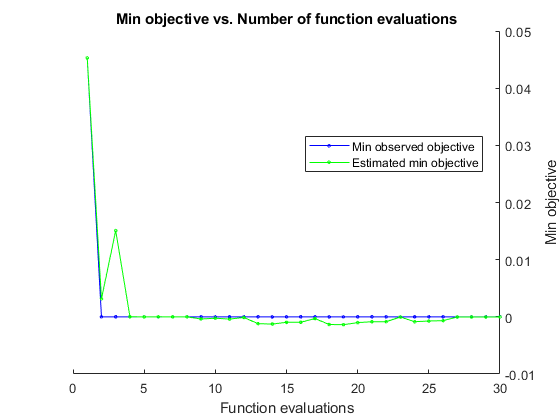

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.045278 |     0.36974 |    0.045278 |    0.045278 |     onevsall |    0.0015668 |     0.030884 |
|    2 | Best   |           0 |     0.36329 |           0 |   0.0031498 |     onevsone |       280.97 |    0.0046476 |
|    3 | Accept |     0.41801 |     0.48566 |           0 |    0.015088 |     onevsone |    0.0017632 |       16.978 |
|    4 | Accept |      0.0125 |     0.30634 |           0 |  2.0209e-05 |     onevsall |       14.152 |       1.7793 |
|    5 | Accept |           0 |      2.2821 |   

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train'; 
Y = y_train;

% Ensemble template 
tTree = templateTree('surrogate','on');
tEnsemble = templateEnsemble('GentleBoost',100,tTree);

Mdl = fitcecoc(X,Y,'Coding',"onevsall",'Learners','svm', "Prior","uniform", "OptimizeHyperparameters","auto",...
    "HyperparameterOptimizationOptions",struct('AcquisitionFunctionName','expected-improvement-plus'));

## Evaluation

% Compute resubstitution classification error to obtain training error 
train_error = resubLoss(Mdl, 'lossfun', 'classiferror');
disp("Training error: " + train_error*100 + "%");

Training error: 0%


% Cross-validate classifier
CVMdl = crossval(Mdl);
% Compute cross-validation classification error: 
cv_error = kfoldLoss(CVMdl, 'lossfun','classiferror');

disp("Validation error: " + cv_error*100 + "%");

Validation error: 0.25%


***Case 1: Low errors***

***    If the validation error is higher than the training error this indicates that there is a case of HIGH VARIANCE***

***    High variance can be solved by adding more training data***

***Case 2: High errors***

***    If both the validation and training error are high this indicates a case of HIGH BIAS***

***    High bias asks for more distinct features***

## Test on same reverberation duration

***Augment test samples***

N_tests = 100;
N_augmentations = N_tests*IRLen;

x_test = zeros(N_bins,N_augmentations);
y_test = zeros(N_augmentations,1);

for k = 1:N_tests
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise, IRms(:,i), 'same');
        
        % cut into 100ms frames with 50% overlap
        noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
        
        % Pyy
        Pyy = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
        x_test(:,index) = normalize(Pyy, 'range');
        y_test(index) = find(any(i==vec,2),1);
    end
end
directions = ["Front"; "Left"; "Back"; "Right"];
y_test = categorical(directions(y_test));

***Predict test samples***

y_pred = predict(Mdl,x_test');
y_pred(randsample(numel(y_pred),5))

ans = 5×1 categorical array
     Front 
     Back 
     Left 
     Front 
     Left 


%numMisclass = sum(~strcmp(,species(idxVal)));
test_error = 1-sum(y_pred==y_test)/N_augmentations;
disp("Test error: " + test_error*100 + "%");

Test error: 0.375%
